# **GENERATION OF A GAUSSIAN WHITE NOISE (**$WN[0,\lambda^2]$**)**

Con il seguente codice si vuole generare un **rumore bianco** **gaussiano **avente *media nulla* e *varianza unitaria *e composto da 10000 campioni.

%wgn: media nulla, varianza unitaria con 10000 campioni
media = 0;
lambda = 1; 
varianza = lambda^2

varianza = 1

N = 10000; 
WN = lambda * randn(1,N) + media; 

Di seguito si vuole verificare che il rumore gaussiano appena generato, `WN`, abbia effettivamente *media nulla *e *varianza unitaria.*

%verifico le proprietà del wgn
mean(WN) 

ans = 0.0017

std(WN); 
var(WN)

ans = 0.9830

Si osservi che, come ci aspettavamo, la **media** si aggira attorno allo *zero* e la **varianza**, così come la deviazione standard, sono prossime al *valore unitario* scelto.

Adesso plottiamo il **rumore bianco gaussiano** generato per osservarne l'*andamento*.

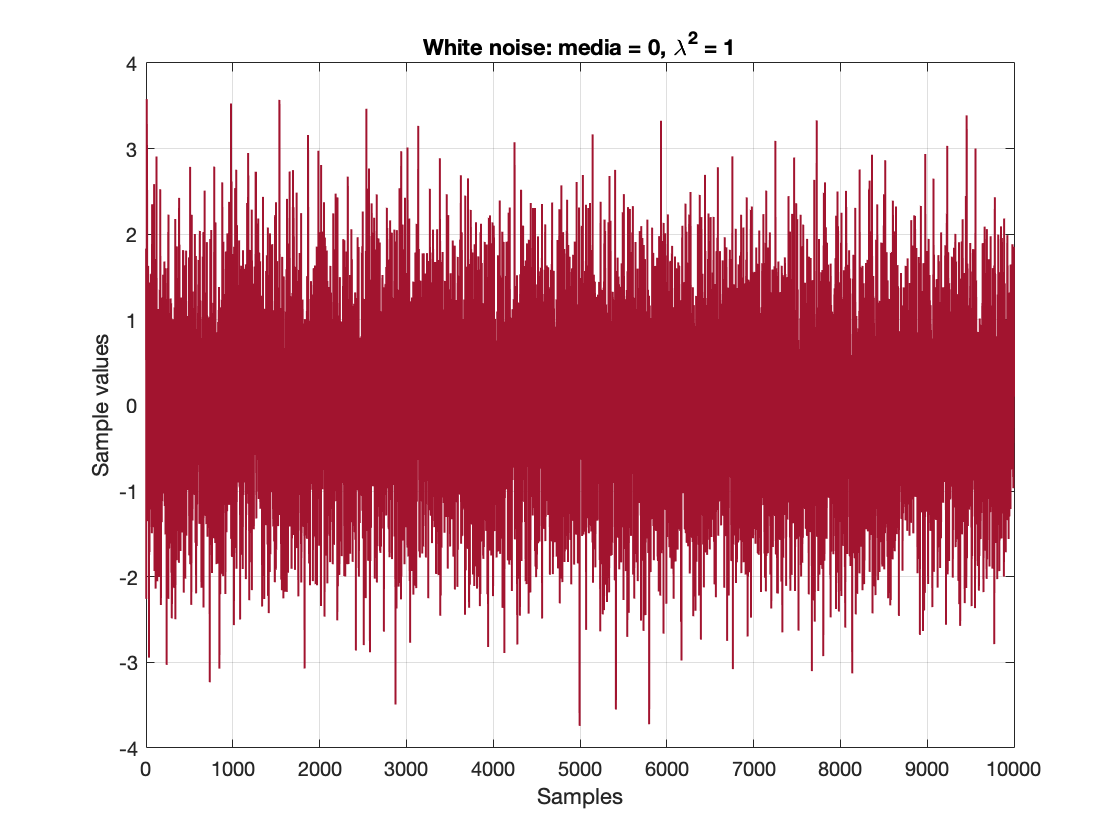

figure('Name','Gaussian White Noise generation');
plot(WN,'LineWidth',1,'Color',[0.635, 0.078, 0.184]), title("White noise: media = 0, \lambda^2 = 1");
xlabel("Samples");
ylabel("Sample values");
grid on;

Di seguito si vuole osservare meglio l'**andamento gaussiano** della *distribuzione di probabilità* del **rumore bianco** precedentemente generato, tramite la realizzazione di un **istogramma**.

n = 100; %numero di bin
f = figure('Name','Probability distribution of the gaussian white noise');
f.Position = [400 418 599 459];
[counts,x] = hist(WN,n);
bar(x,counts/trapz(x,counts),'EdgeColor','k','LineWidth',1.35,'EdgeAlpha',0.95); % plot dell'istogramma
hold on;

`NOTA:` `'counts' `è un vettore riga contenente il *numero di elementi* per ogni bin (colonna costituente l'istogramma), mentre x è un vettore riga che contiene il *valore centrale* di ogni bin.

Realizziamo ora la **funzione di densità di probabilità **(**PDF**) di una *variabile aleatoria gaussiana* data da:


$$f_x(x) = \frac{1}{\lambda\sqrt{2\pi}} e^{- \frac{(x-\mu)^2}{2\lambda^2}}$$


dove $\mu$è la media della variabile aleatoria e $\lambda^2$ la relativa varianza.

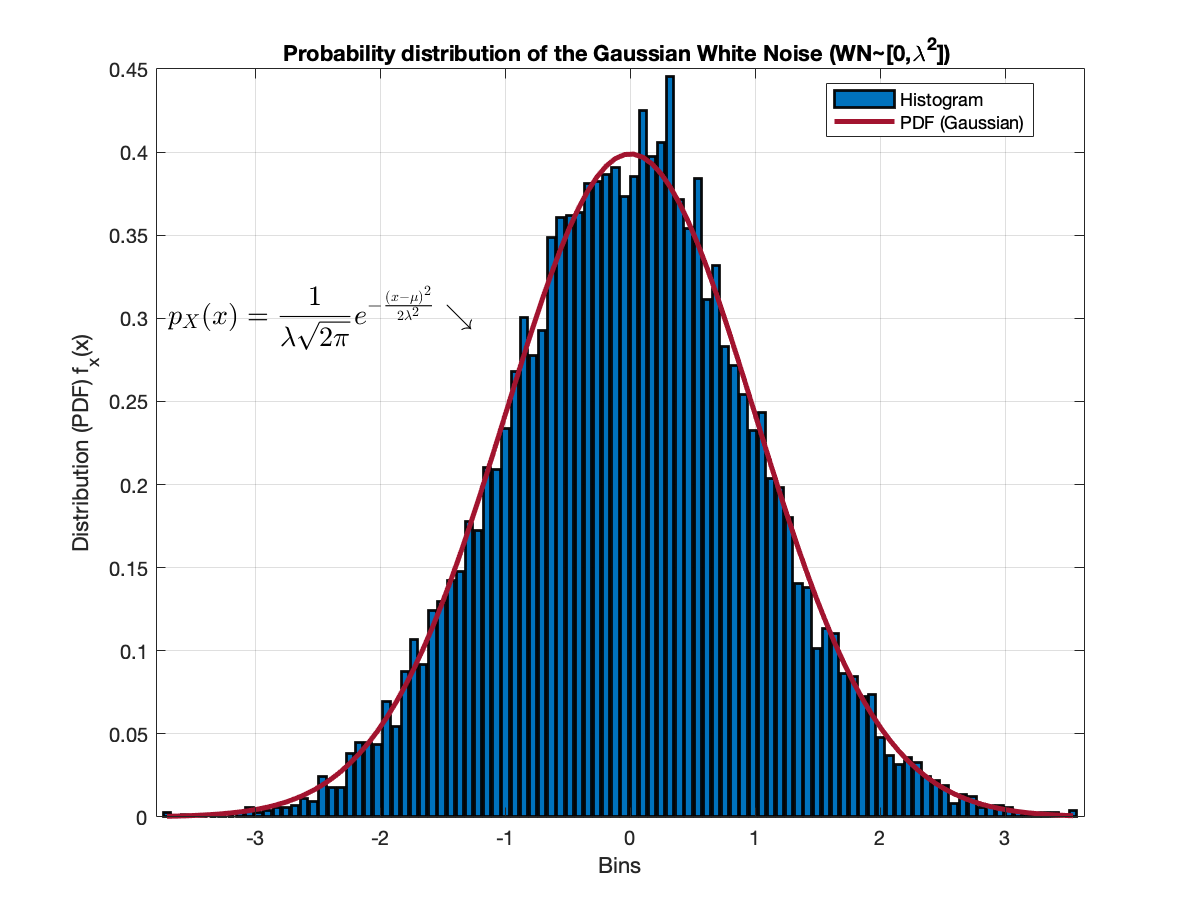

PDF_gauss = (1/(sqrt(2*pi)*lambda)) * exp(-((x-media).^2)/(2*lambda^2)); 
plot(x,PDF_gauss,'LineWidth',2.5,"Color",[0.635, 0.078, 0.184]); 
pdf ='$$p_X(x)=\frac{1}{\lambda \sqrt{2\pi}}e^{-\frac{(x-\mu)^2}{2\lambda^2}} \searrow$$';
text(-3.7,0.3,pdf,'Interpreter','latex','FontSize',14);
hold off;
grid on;
xlabel('Bins');
ylabel('Distribution (PDF) f_x(x)')
title("Probability distribution of the Gaussian White Noise (WN~[0,\lambda^2]) ");
legend('Histogram','PDF (Gaussian)','Location',"best");

Sappiamo, inoltre, che la cross-correlazione fra due sequenze $x$ e $y$ a istanti di tempo separati da un certo ritardo $\tau$ (lag) è descritta da:


$$ R_{xy_{i}} = Corr(x,y)_i = \sum_{j = -\infty}^\infty x_jy^*_{j+i}$$


Essa misura la somiglianza tra un vettore $x$ e e una copia traslata di un vettore $y
$ come funzione del ritardo $\tau$ (lag). L'autocorrelazione è un caso particolare di cross-correlazione, nel caso in cui $y = x$, pertanto, esprime la correlazione di una data sequenza con se stessa come funzione del ritardo.

Inoltre, introduciamo il concetto di funzione di autocorrelazione :

$R_{XX}(\tau) = E[x(t)x^*(t-\tau)] = \sigma^2\delta(\tau)$,

dove $\tau = t_1 - t_2$

In particolare, un **processo stocastico bianco** (**rumore bianco**) nel dominio continuo del tempo, $$x(t)$ con $t \in \mathbb{R}$$, è caratterizzato dalle seguenti proprietà:

- $\mu_X(t) = E[x(t)] = 0$;

- 
$$R_{XX}(t_1,t_2) = E[x(t_1)x^T(t_2)] = \sigma^2\delta(t_1-t_2)$$


Ciò implica che un **rumore bianco** ha una **funzione di autocorrelazione ***nulla ovunque*, eccetto in $\tau = 0$, dove $\tau = t_1 - t_2$.

Con il seguente codice, quindi, si intende mostrare come non ci sia alcuna autocorrelazione per il rumore bianco generato, eccetto in zero.

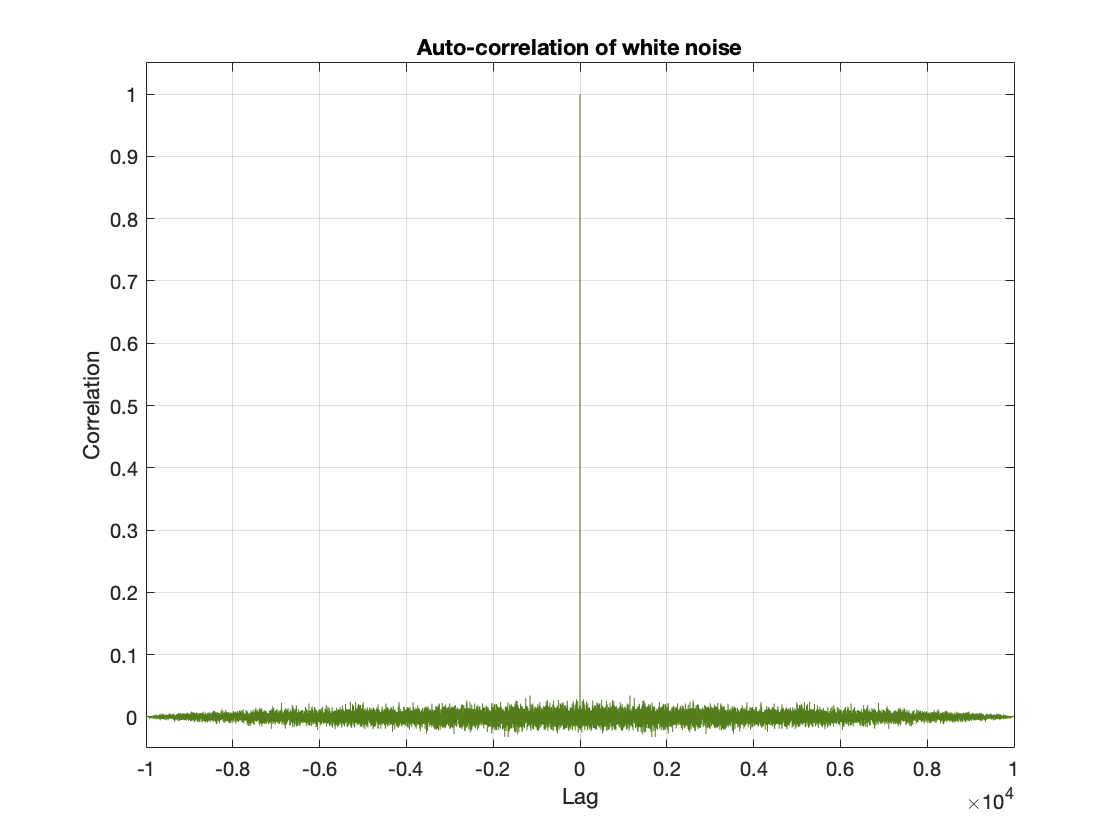

figure('Name','Auto-correlation function of the white noise')
[autocorr,lag] = xcorr(WN,'normalized');
p = plot(lag,autocorr);
p.Color = [.33 .49 .11];
title('Auto-correlation of white noise');
xlabel('Lag');
ylim([-0.05 1.05]);
ylabel('Correlation');
grid on;